# DSZOB, cvičenie 2.

## **Zadanie:**

## **Úloha 1 – Základné generovanie signálov**

Vygenerujte a vhodne vizualizujte nasledovné signály (vzorkovacia frekvencia 44.1 kHz, časový úsek 3 sekundy):

- Sínusový signál s frekvenciou zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou = 0,6.

- Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu <0,2:0,5>.

- Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu  <0,1:0,4>.

- Generujte zložený signál ako súčet  z predchádzajúcich vygenerovaných signálov. 

- K zloženému signálu aditívne pripočítajte šum s magnitúdou z rozsahu <0,01:0,05>.

(pomôcka: funkcia *rand()* alebo  *randn() )*

Vygenerované signály si vypočujte po sebe v poradí generovania (zložený signál na záver).

Vygenerované signály vizualizujte!

Pozn.: Môžete sa pokúsit o akord (vid tab. dole)

## **Tab. Temperované ladenie - frekvencie**

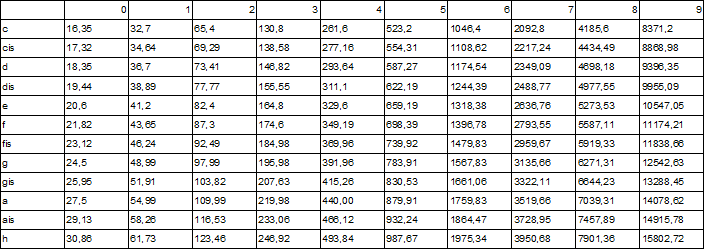

**Príklady akordov / Tóny, z ktorých sa skladá:**

- Cdur / **C, E, G**

- Gdur / **G, H, D**

- Amoll / **A, C, E**

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

% Solution
clear
% Values from table
c0 = 16.35;
cis0 = 17.32;
d0 = 18.35;

t = 3; % Measured time span
samp = 44100;   % Sampling rate 44.1kHz

mag1 = .6;
freq1 = (c0*2*pi);

%First signal
x1 = [0:1/samp:t];
y1 = mag1 * sin(x1 * freq1);

%Second signal
mag2 = .2 + mod(rand(), (.5 -.2));  %Vector with random numbers from given magnitude range (0.2, 0.5)
freq2 = (2*pi*cis0);
y2 = mag2 .* sin(x1 * freq2);   %We use x1 again because we are always checking 3 second time span

%Third signal
mag3 = .1 + mod(rand(), (.4 -.1));  %Vector with random numbers from given magnitude range (0.2, 0.4)
freq3 = (2*pi*d0);
y3 = mag2 .* sin(x1 * freq3);

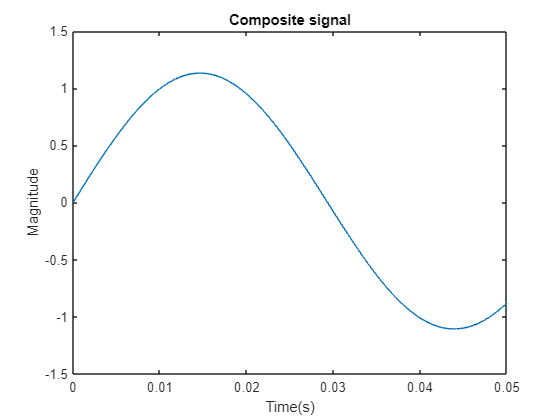

%Summed signal
sum_sig = y1 + y2 + y3;
plot(x1,sum_sig);
xlim([0,0.05])
xlabel('Time(s)');
ylabel('Magnitude');
title("Composite signal");

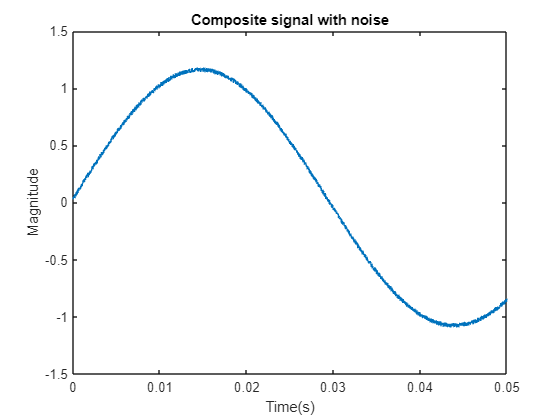

%Generating noise vector
noise = 0.01 + mod(rand(1,length(x1)), 0.05 - 0.01);
sum_sig = sum_sig + noise;
plot(x1,sum_sig);
xlim([0,.05])   % Zoom onto a section to show noise
xlabel('Time(s)');
ylabel('Magnitude');
title("Composite signal with noise");

## **Úloha 2**

Znížte vzorkovaciu frekvenciu u Vami vygenerovaného signálu:

- na polovicu

- na štvrtinu

- na hranicu danú Nyquistovým  teorémom

- a aj s porušením Nyquistovho  teorému. 

Vizualizujte dané signály v jednom grafe. Signál si vypočujte a vyhodnoťte kvalitu.

Pomôcky : funkcia: *downsample()*

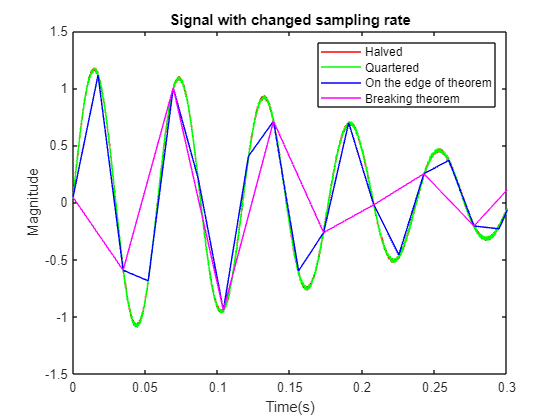

% Riesenie / Solution
halved_x = downsample(x1, 2);
halved_y = downsample(sum_sig, 2);

plot(halved_x, halved_y, "red");
xlabel('Time(s)');
ylabel('Magnitude');
title("Signal with changed sampling rate");
hold on

quartered_x = downsample(x1, 4);
quartered_y = downsample(sum_sig, 4);

plot(quartered_x, quartered_y, "green");
hold on

edge_sample = 2*round(samp/(max([freq1, freq2,freq3])));  
edge_x = downsample(x1, edge_sample);
edge_y= downsample(sum_sig, edge_sample);

plot(edge_x, edge_y, "blue");
hold on

break_x = downsample(x1, round(edge_sample*2));
break_y = downsample(sum_sig, round(edge_sample*2));

plot(break_x, break_y, "magenta")
legend('Halved', 'Quartered', 'On the edge of nquist theorem', 'Breaking nquist theorem');
xlim([0,.3])